# Tutorial 3 - Sea Surface Heights (SSH)

What you will need (from Stellar):

- m_coast.mat

- drifters.mat

- plotmap.m

- movie2gif.m

- SSH_North_Atlantic_2010_2020.nc

- SSH_Tropical_Eastern_Pacific_2010_2020.nc

Additonally you need the following toolboxes installed (remember to have everything added to the Matlab search path) :

- jlab ([ https://www.mathworks.com/matlabcentral/fileexchange/52885-jlab-a-matlab-toolbox-for-data-analysis](https://www.mathworks.com/matlabcentral/fileexchange/52885-jlab-a-matlab-toolbox-for-data-analysis)) 

- cmocean ( [https://www.mathworks.com/matlabcentral/fileexchange/57773-cmocean-perceptually-uniform-colormaps](https://www.mathworks.com/matlabcentral/fileexchange/57773-cmocean-perceptually-uniform-colormaps) )

Throughout this livescript, key tasks will be indicated as follows:

**!! Q0 **- *Look for tasks like these. There are 8 in this livescript.*

Please be sure to complete these tasks, as we will be checking for their  completion while marking.

Work through the script and fill in where needed.  At the end export the livescript as html and/or as pdf, which will be your report in addition to your live script. For the final report that you hand it, only keep the important parts and delete the rest of the code.

Make sure that the file contains:

- Well-documented code

- Your answers to specific questions asked within the scrip

- Your figures with proper labeling, i.e. axis and colorbar labels, as well as titles and legends (where needed). Add figure captions for each figure (they can bed added as text below the figure in the live script)

- Short description on the figures and their interpretation as specified within the live script.

Please include your name in the file name, e.g. SSH_GlennLiu.mlx

Check the list at the end of the livescript for further instructions.

## Drifter Data

We will be using a subset of the drifter data (**jdata)** supplied by Jonathan Lilly. His data analysis toolbox **jlab **has been introduced to you in the Matlab tutorial introduction.  The full dataset can be downloaded here:

[http://www.jmlilly.net/jmldata.html](http://www.jmlilly.net/jmldata.html) 

clear; close all
addpath(genpath('/home/sryan/Documents/MATLAB/functions_and_co/'))

%% load drifter data
load drifters.mat;

% which variables have been loaded
whos

  Name        Size              Bytes  Class    Attributes

  lat       736x1             8515944  cell               
  lon       736x1             8515944  cell               
  time      736x1             8515944  cell               



As in the introduction tutorial, we see that the data are saved as cells. Similarly to CTD casts, each drifter timeseries has a different length, which would make it difficult to save everything in a matrix. Remember, an alternative to cells are structs.

% check out first drifter
lon(1)

ans = 1×1 cell array
    {1745×1 double}


We see that each cell includes a vector and the first drifter timeseries has the length 1745. To access the data we use the waivy brace

lon{1}(1)

ans = -85.7080

## **Plot Trajectories**

Let's start by plotting all the trajectories. One of the popular toolboxes for mapping in Matlab is m_map ([https://www.eoas.ubc.ca/~rich/map.html](https://www.eoas.ubc.ca/~rich/map.html)). To simplify things, we will be using the plotmap() function to automatically draw the coastlines based on the m_coasts.mat file.

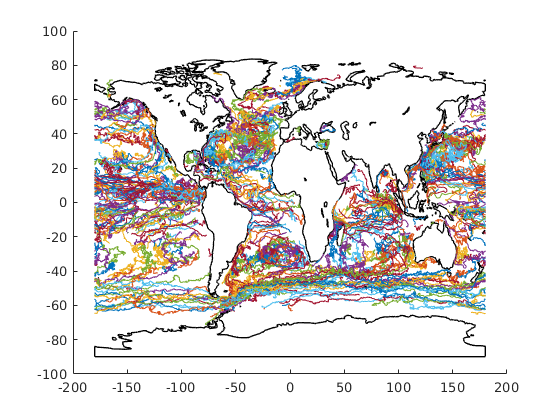

figure(1);clf, hold on
% use plotmap to draw coastlines
plotmap
% to plot all trajectories, we need a loop
for i = 1:length(lon)
    plot(lon{i},lat{i},'.','markersize',0.1)
end

You can see all the squiggly lines representing different drifters. 

**Not sure if i am missing a Q1 here, seemed to start with Q2?**

We can choose one drifter to look at how much data there is in one particular drifter trajectory. This becomes more visible if we plot each measurement as a circle, i.e. 'o'.

Fill in the plotting commands below!

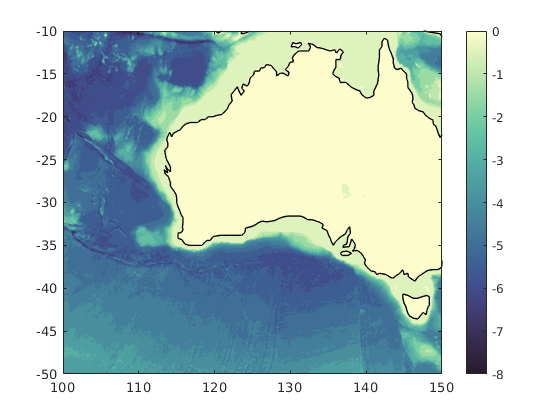

% choose a random number for drifter
ind = 80;

lon_drifter = lon{ind};
lat_drifter = lat{ind};

figure(2),clf
% check out topoplot from jlab toolbox
topoplot([],-8:0.5:0)
plotmap % matlab script plotting coastlines
hold on
%plot(lon_drifter...)
% mark beginning of trajectory red
%plot()
cmocean('-deep')    % colormap for bathymetry
set(gca,'layer','top')    % What does this do? -- puts the tick marks above the plot
colorbar
% use xlim and ylim to zoom into the region
% hey look, its austrailai
xlim([100 150])
ylim([-50 -10])

You can also use the interactive tools in the top-right corner of the figure to zoom in, which even allows you to copy xlim,ylim code.

## **The Time Variable**

It is always wise to get familiar with the time coordinate of each individual dataset as their are many different ways and formats times are save in.

% To find out when the drifter was released, type
format long
time_drifter = time{ind}

time_drifter = 	1.0e+05 *

   7.286062500000000
   7.286065000000000
   7.286067500000000
   7.286070000000000
   7.286072500000000
   7.286075000000000
   7.286077500000000
   7.286080000000000
   7.286082500000000
   7.286085000000000


These numbers might not make sense to you, as it is in Matlab's datenum format. In order to see the real date, use the *datestr *function, which converts a Matlab date number to a human-readable string. 

datestr(time_drifter(1))

ans = '08-Nov-1994 06:00:00'

Matlab datenum is just the number of days since some particular time. Which? Find out by typing:

beginning = datestr(0)

beginning = '00-Jan-0000'

Another important thing to check the temporal resultion of your data, i.e. how often did the drifter transmitt its position and do we have any data gaps?

Since the drifter time is in real days, the temporal resultion of the data is simply the difference between the consecutive drifter measurements.

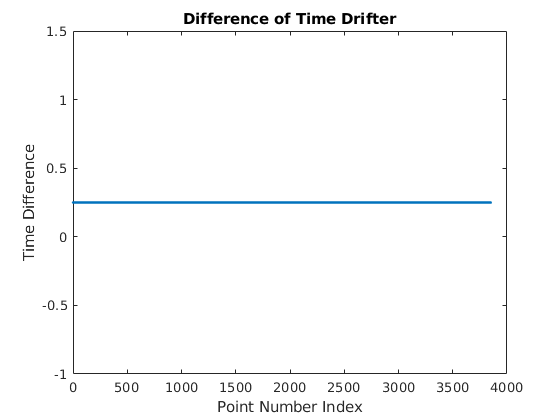

% plot the time difference between each data point
figure(3);clf
plot(diff(time_drifter),'.')
title('Difference of Time Drifter')
xlabel('Point Number Index')
ylabel('Time Difference in Days')

**!! Q2 - ***Answer the following questions:*

- *What is the temporal resolution?*

- *Are there any data gaps? How do you know?*

**Your Answer****: The temporal resolution of this graph appears to be 0.25 or 1/4 of a day between points, equivalent to 6 hours. There don't appear to be any data gaps because the line is continuously on the 0.25, if there were gaps, there would be points possible elsewhere or returned errors.**

## Load SSH data

The Sea Surface Height (SSH) data we are using has been dowloaded from this website:

[http://marine.copernicus.eu/services-portfolio/access-to-products/](http://marine.copernicus.eu/services-portfolio/access-to-products/)

Daily fields are available from 1993-present and at a spatial resolution of 1/4deg in latitude and longitude. We are again using subsets of the full data set.

Data harvesting has become more tricky due to the increasing amount of available data. One of the lectures will give you some insight on this but for now you don't have to worry about it.

**!! Q3 - **Y*our task:*

- Choose either the North Atlantic or the Tropical Eastern Pacific as your study region (these are the regions where we extracted SSH fields)

- Plot the time mean of the SSH field

- Find a float in that region by looking at the starting position of each trajectory (there will be some help)

% Indicate "NA" (North Atlantic) or "PA" (Tropical Eastern Pacific) as your region of choice.
region = "PA";

% Set netCDF file name based on choice.
if strcmp(region,"NA") == 1
    disp("Loading SSH data for North Atlantic...")
    ncname = "SSH_North_Atlantic_2010_2020.nc"
elseif strcmp(region,"PA") == 1
    disp("Loading SSH data for Tropical Eastern Pacific...")
    ncname = "SSH_Tropical_Eastern_Pacific_2010_2020.nc"
else
    disp("Invalid entry for region. Please enter 'NA' or 'PA'.")
end

Loading SSH data for Tropical Eastern Pacific...


ncname = "SSH_Tropical_Eastern_Pacific_2010_2020.nc"

% Examine the metadata for the netCDF file
ncdisp(ncname)

Source:
           /home/kfung/Downloads/Climate/CVD_Tutorials/Tutorial03_SSH/SSH_Tropical_Eastern_Pacific_2010_2020.nc
Format:
           netcdf4
Dimensions:
           latitude  = 160
           time      = 3575
           longitude = 200
Variables:
    latitude 
           Size:       160x1
           Dimensions: latitude
           Datatype:   single
           Attributes:
                       _FillValue          = NaN
                       axis                = 'Y'
                       bounds              = 'lat_bnds'
                       long_name           = 'Latitude'
                       standard_name       = 'latitude'
                       units               = 'degrees_north'
                       valid_max           = 89.875
                       valid_min           = -89.875
                       _ChunkSizes         = 50
                       _CoordinateAxisType = 'Lat'
    time     
           Size:       3575x1
           Dimensions: time
           Dataty

% Load the variables
sshout     = ncread(ncname,'adt'); % see the output from ncdisp to understand 'adt'%
sshlon     = ncread(ncname,'longitude');
sshlat     = ncread(ncname,'latitude');
sshtimeout = ncread(ncname,'time');

% Permute the data from [time x lat x lon] to [lon x lat x time]
ssh = permute(sshout,[3,2,1]);

% Create the time-mean of the data by issuing the command
ssh_mean=mean(ssh,3);
% What is the 3 for?
% the three is looking at the third non-one dimension of the array sst

Note also that the time variable in the netCDF is loaded in as "days since 2010-01-01". For comparison with the drifter data, which is days since 000-01-01, we need to do some additional conversions below...

% Convert to MatLab datetime object (human readable form)
ssh_datetime = datetime(2010,1,1,'Format','dd-MMM-yyyy HH:mm:ss') + caldays(sshtimeout)

ssh_datetime = 3575×1 datetime array
   01-Jan-2010 00:00:00
   02-Jan-2010 00:00:00
   03-Jan-2010 00:00:00
   04-Jan-2010 00:00:00
   05-Jan-2010 00:00:00
   06-Jan-2010 00:00:00
   07-Jan-2010 00:00:00
   08-Jan-2010 00:00:00
   09-Jan-2010 00:00:00
   10-Jan-2010 00:00:00
   11-Jan-2010 00:00:00
   12-Jan-2010 00:00:00
   13-Jan-2010 00:00:00
   14-Jan-2010 00:00:00
   15-Jan-2010 00:00:00
   16-Jan-2010 00:00:00
   17-Jan-2010 00:00:00
   18-Jan-2010 00:00:00
   19-Jan-2010 00:00:00
   20-Jan-2010 00:00:00
   21-Jan-2010 00:00:00
   22-Jan-2010 00:00:00
   23-Jan-2010 00:00:00
   24-Jan-2010 00:00:00
   25-Jan-2010 00:00:00
   26-Jan-2010 00:00:00
   27-Jan-2010 00:00:00
   28-Jan-2010 00:00:00
   29-Jan-2010 00:00:00
   30-Jan-2010 00:00:00



% Convert to datenumber (days since 0000-01-01)
sshtime = datenum(ssh_datetime)

sshtime =       734139
      734140
      734141
      734142
      734143
      734144
      734145
      734146
      734147
      734148



% You can also just directly do the conversion (same as above, but in one line)
sshtime2 = double(datenum(datetime(2010,1,1)) + sshtimeout)

sshtime2 =       734139
      734140
      734141
      734142
      734143
      734144
      734145
      734146
      734147
      734148


disp(max(abs(sshtime-sshtime2))) % Check that they are indentical

     0



## Plot time-mean SSH field

**!! Q4** - *Write the code below to plot the time-mean SSH field.*

- Use the contourf function and define contour levels

- As always, add a colorbar and labels

- In the title of your plot, display the date range over which you averaged the SSH fields

- You might get an error message because the ssh_mean matrix is in the form lonxlat instead of latxlon. In this case use ' to transpose the matrix.

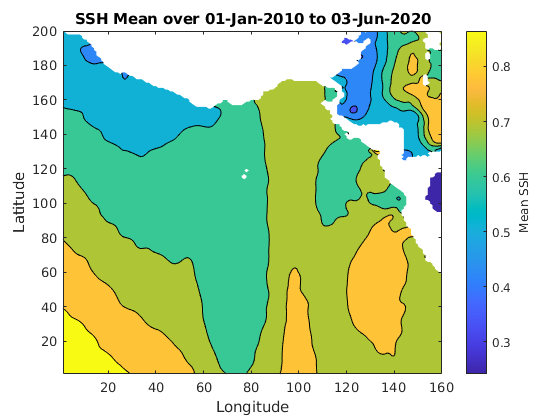

% place your code here
figure(4),clf
contourf(ssh_mean,7)
title(['SSH Mean over ' datestr(ssh_datetime(1)) ' to ' datestr(ssh_datetime(3575))])
xlabel('Longitude')
ylabel('Latitude')
h = colorbar;
set(get(h,'label'),'string','Mean SSH');

**Find drifters in your region**

Now, we want to find floats that were actually in the region that you chose and the given time period. To do this, we have to play a little with our data since each trajectory is currently stored in a separate cell. To make the search easier, we save the starting and end points of each trajectory in a new variable.

% loop to save start and end positions
for i = 1:length(lon)
    lon_start(i) = lon{i}(1);
    lon_end(i) = lon{i}(end);
    lat_start(i) = lat{i}(1);
    lat_end(i) = lat{i}(end);
    time_start(i)  = time{i}(1);
    time_end(i) = time{i}(end);
end

% define area you want to search in
lon_bnds = [min(sshlon),max(sshlon)];
lat_bnds = [min(sshlat),max(sshlat)];
time_bnds = [datenum(2008,01,01) datenum(2018,01,01)];

% see if any drifter is in that region
j=0;
drifter_ind = [];
for i = 1:length(lon_start)
    if (lon_start(i)>=lon_bnds(1) && lon_start(i)<=lon_bnds(2) && ...
            lat_start(i)>=lat_bnds(1) && lat_start(i)<=lat_bnds(2) && ...
            lon_end(i)>=lon_bnds(1) && lon_end(i)<=lon_bnds(2) && ...
            lat_end(i)>=lat_bnds(1) && lat_end(i)<=lat_bnds(2) && ...
            time_start(i)>= time_bnds(1)  && time_end(i)<=time_bnds(2))
        j = j+1;
        drifter_ind(j) = i;
    end
end

whos drifter_ind

  Name             Size            Bytes  Class     Attributes

  drifter_ind      1x8                64  double              



The length of drifter_ind shows us how many trajectories start and end in our box. We can plot the trajectories on our map. The values in drifter_ind give us the indices for the trajectories.

**Plot drifters that were detected**

I always like to visualize my steps. So let's plot all the drifters we detected.

figure(5),clf,hold on
plotmap
clear pp
for i = 1:length(drifter_ind)
    pp(i) = plot(lon{drifter_ind(i)},lat{drifter_ind(i)});
end
xlim(lon_bnds)
ylim(lat_bnds)
title('Drifter Map')
xlabel('Longitude')
ylabel('Latitude')
box on

You can play with this to finally choose your one drifter who you would like to investigate further. To make identification easier, you could plot a legend indicating the index of the floats

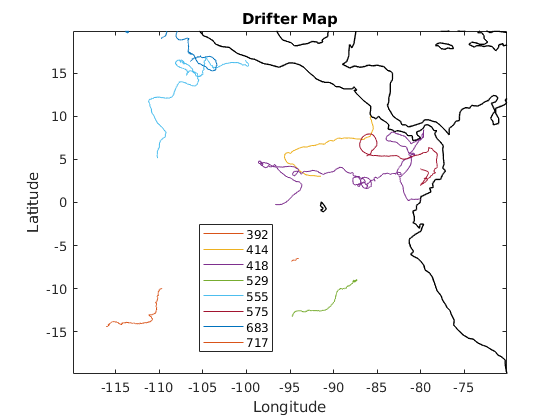

legend(pp,num2str(drifter_ind(:)),'location','best')

**Find associated time range of SSH fields**

In order to plot the drifter trajectory on the SSH field during that time, we need to find out the time period during which the drifter was deployed.

% choose index for your drifter
% ind_drifter = ...;

% ind_drifter = drifter_ind(end)
% picked the purple one because I liked it the best
ind_drifter = 418;

% first extract again the data for our specific drifter
lon_drifter = lon{ind_drifter};
lat_drifter = lat{ind_drifter};
time_drifter = time{ind_drifter};

% what is the first and last date?
datestr(time_drifter(1))

ans = '26-Apr-2009 18:00:00'

datestr(time_drifter(end))

ans = '19-Feb-2010'


% find sshtime in that range
ind_time = find(sshtime>=time_drifter(1) & sshtime<=time_drifter(end));
whos ind_time

  Name           Size            Bytes  Class     Attributes

  ind_time      50x1               400  double              



Great, now we can cut out the ssh data we need!

ssh_drifter = ssh(:,:,ind_time);
ssh_time_drifter = sshtime(ind_time);
whos ssh_drifter

  Name               Size                   Bytes  Class     Attributes

  ssh_drifter      200x160x50            12800000  double              




% delete old variables
% clear ssh sshtime

**!! Q5 -*** Your task:*

- Now derive the mean SSH field only over the drifter's time period, i.e. the time-mean of ssh_drifter and plot the trajectory on top. (Remember to check which dimension represents time)

- Comment on how well the drifter trajectory and the time-mean sea surface height agree. Hint: Think about which direction the pressure gradient is going and which direction you would expect the geostrophic current to go.

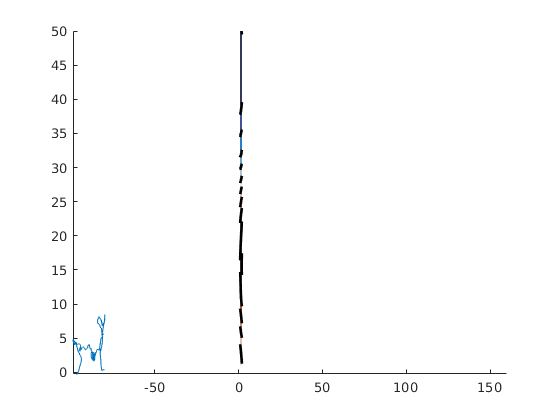

% Place your code here
% Permute the data from [time x lat x lon] to [lon x lat x time]
ssh_mydrifter = permute(ssh_drifter,[3,2,1]);

% Create the time-mean of the data by issuing the command
ssh_meandrifter=mean(ssh_mydrifter,3);
% you might want to raw your trajectory a little thicker. You can do that by adding
% 'linewidth',2 just before the closing brace.

figure(6),clf,hold on
contourf(ssh_meandrifter,'linewidth',2)
plot(lon_drifter,lat_drifter)
cmocean('balance',length(0:0.02:1)-1)

**Answer:**** I expected the drifter to follow the current, which is being affected by the pressure gradient. I would expect a lower pressure gradient to draw the drifter in on the current, which seems to be represented here as the SSH goes from high to low.**

**Make a movie of time-varying SSH and your float trajectory**

You can get most information on how the sea surface height and the drifter trajectory are related by making an animation of the two.

Let's begin by first making a movie of only the sea surface height. You will have to write some code that will show individual snapshots in the array ssh, based on the value of the variable. Note that this is very similar to what you've done in the ENSO Matlab Tutorial, when you plotted all snapshots of SST. You might want to look back into that lab to see how you did it there.

**!! Q6** - *Write the code below to make a movie of sea surface height.*

*    Hint: You can use pcolor() or contourf(). Each frame correspondings to a single timestep.*

% Place your code here
% remember this code will most likely not work within the live script, so copy it to the
% command window to execute or use F9 to evaluate marked code

figure(7),clf
for t = 1:length(ssh_time_drifter)
    
end

% add suitable labels and colorbar and make sure the range of the colormap is set (using caxis), so that it
% doesn't change in each time step.

Next we want to add the location of the drifter. The problem is, that the times associated with ssh and drifter data are not the same, i.e. they have different temporal resolutions.

To do this you need to:

- find the time associated with the ssh that you are plotting, i.e. sshtime(t)

- find the location in time_drifter that corresponds to that time, i.e. ind=find(time_drifter==sshtime(t));

- plot the corresponding lon_drifter and lat_drifter

- Add again colorbar, labels, title with current date

Also we want to save the sequence of figures as an actual movie file. Check out the commented code below, which will do the job for you and save your movie as a .gif file. For your final report, you can insert the .gif into the mlx file by using *INSERT > Image *in the task bar on top.

**!! Q7** - *Write the code below to make a movie of sea surface height and the position of your drifter.*

% place your code here

f=figure(8);clf,hold on
set(f,'color','w','visible','off')      % don't show all figures
%M=[];
for t = 1:length(ssh_time_drifter)
    
    %im=getframe(gcf);
    %M=[M im];
end
% save frames to gif
%movie2gif(M,'./ssh_drifter.gif','LoopCount',Inf,'DelayTime',0.2)
% to only play the video in as a figure try this:
%movie(f,M)

## Your report

Your final report should only contain the important plots. You may want to create two files: one for yourself that includes everything above and one for marking that only includes the relevant material. This should include:

- A plot with the available drifters in the region you chose, including coastlines

- Our gif animation

- A snapshot of SSH at some time where you can see an interesting feature

- All answers to questions asked throughout

- Remember labels etc. and figure captions (including the one below).

**!! Q8 -** *Give a brief (<100 words) description of:*

- how the drifter location changes in relation to SSH

- what you would expect the ocean circulation doing in your snapshot of SSH

**The drifter**

**In my snapshot of SSH, I would expect the ocean circulation to be**

## Optional extras (unmarked)

- You could add a 'tail' showing the trajectory of the drifter for previous ssh snapshots. Try and find out for yourself how to add this to the movie.